%%%Nominal motor values
motor.kt = 0.000872234;
motor.J  = 2.55E-5;
motor.b  = 1.00023E-05;
motor.c  = 0.000435786;
motor.L  = 0.000176564;
motor.R  = 1.23424;
motor.Ke = 0.00966471; 

initial = cell2mat(struct2cell(motor));

%%%1. Read data measured from the experiment
nombre_archivo = 'RPMdata1.xlsx';
%dt = 1E-3;      %%Set sample time
dt = 1;      %%Set sample time

%%%Read Excel file
datos = readtable(nombre_archivo);
%%%Add voltage equivales
datos.voltage = ((datos.Input_PWM-1100)*(24/800))-12; %% asuming from -12 to 12 v
%%%Interpolate data to set the desired sampple time
[newDatos.time,newDatos.RPM] = setSampleTime(datos.time_s,datos.Velocidad_rpm,dt);
[~,newDatos.current] = setSampleTime(datos.time_s,datos.Current_A,dt);
[~,newDatos.voltage] = setSampleTime(datos.time_s,datos.voltage,dt);
%%%Update Signs
newDatos.RPM = sign(newDatos.voltage).*newDatos.RPM;
newDatos.current = sign(newDatos.voltage).*(newDatos.current-0.025);

% 2. Represent the estimation data as an |iddata| object. 
y = [newDatos.RPM*pi/30;newDatos.current]';
u = newDatos.voltage';

z = iddata(y, u, dt, 'Name', 'DC-motor');
%%
% 3. Specify input and output signal names, start time and time units. 
z.InputName = 'Voltage';
z.InputUnit =  'V';
z.OutputName = {'Angular rate', 'Motor current'};
z.OutputUnit = {'rad/s', 'A'};
z.Tstart = 0;
z.TimeUnit = 's';

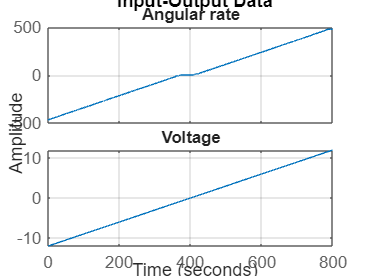

% 4. Plot the data.
%
% The data is shown in two plot windows.
figure('Name', [z.Name ': Current input -> Angular rate output']);
plot(z(:, 1, 1)); grid on;  % Plot first input-output pair (Voltage -> Angular position).

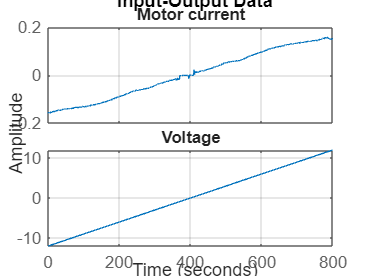

figure('Name', [z.Name ': Voltage input -> Motor current output']);
plot(z(:, 2, 1));  grid on; % Plot second input-output pair (Voltage -> Angular velocity).

%% Linear Modeling of the DC-Motor
% 1. Represent the DC motor structure in a function.  
%%%Check BrushelessModel.m file
%%


% 2. Represent the DC motor dynamics using an |idnlgrey| object.
%
% The model describes how the inputs generate the outputs using the state
% equation(s).
FileName      = 'BrushelessModel';       % File describing the model structure.
Order         = [2 1 2];           % Model orders [ny nu nx].
%Parameters    = [1; 0.28];        % Initial parameters. Np = 2.
Parameters    = initial';          % Initial parameters. Np = 3.
InitialStates = [-500; 0.15-0.025];            % Initial initial states.
%InitialStates = [0; 0];            % Initial initial states.
Ts            = 0;                 % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts, ...
                'Name', 'DC-motor');

%%
%
% 3. Specify input and output names, and units.
set(nlgr, 'InputName', 'Voltage', 'InputUnit', 'V',               ...
          'OutputName', {'Angular rate', 'Motor current'}, ...
          'OutputUnit', {'rad/s', 'A'},                         ...
          'TimeUnit', 's');

%%
% 
% 4. Specify names and units of the initial states and parameters.
nlgr = setinit(nlgr, 'Name',  {'Angular rate', 'Motor current'});
nlgr = setinit(nlgr, 'Unit', {'rad/s', 'A'});
%nlgr = setpar(nlgr, 'Name', {'Torque constant' 'Rotor inertia' 'Constante de friccion viscosa' 'Inductancia' 'Resistencia' 'Constante contraelectromotriz' });
%nlgr = setpar(nlgr, 'Unit', {'N*m/A' 'kg*m^2' 'N*m*s' 'H' 'R' 'V/(Rad/s)' });

nlgr = setpar(nlgr, 'Name', {'Torque constant' 'Rotor inertia' 'Constante de friccion viscosa' 'Constante de friccion de Coulomb' 'Inductancia' 'Resistencia' 'Constante contraelectromotriz' });
nlgr = setpar(nlgr, 'Unit', {'N*m/A' 'kg*m^2' 'N*m*s' 'N*m*s' 'H' 'R' 'V/(Rad/s)' });

%nlgr = setpar(nlgr, 'Name', {'Torque constant' 'Rotor inertia' 'Constante de friccion viscosa' ...
%    'Constante de friccion de Coulomb' 'Inductancia' 'Resistencia' 'Constante contraelectromotriz' 'Starting Torque' ...
%    'Stribeck angular rate'});
%nlgr = setpar(nlgr, 'Unit', {'N*m/A' 'kg*m^2' 'N*m*s' 'N*m*s' 'H' 'R' 'V/(Rad/s)' 'N*m' 'rad/s'});

%% 
%
% You can also use |setinit| and |setpar| to assign values, minima, maxima,
% and estimation status for all initial states or parameters
% simultaneously.
%
% 5. View the initial model.
%
% a. Get basic information about the model.
%
% The DC-motor has 2 (initial) states and 2 model parameters.
size(nlgr)

Nonlinear grey-box model with 2 outputs, 1 inputs, 2 states and 7 parameters (7 free).


%%
%
% b. View the initial states and parameters.
%
% Both the initial states and parameters are structure arrays. The fields
% specify the properties of an individual initial state or parameter. Type
% |help idnlgrey.InitialStates| and |help idnlgrey.Parameters| for
% more information.
nlgr.Parameters(1).Minimum = 0;
nlgr.Parameters(1)

ans = struct with fields:
       Name: 'Torque constant'
       Unit: 'N*m/A'
      Value: 8.7223e-04
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(2).Minimum = eps(0);
nlgr.Parameters(2).Fixed = 1;
nlgr.Parameters(2)

ans = struct with fields:
       Name: 'Rotor inertia'
       Unit: 'kg*m^2'
      Value: 2.5500e-05
    Minimum: 4.9407e-324
    Maximum: Inf
      Fixed: 1


nlgr.Parameters(3).Minimum = 0 ;
nlgr.Parameters(3)

ans = struct with fields:
       Name: 'Constante de friccion viscosa'
       Unit: 'N*m*s'
      Value: 1.0002e-05
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(4).Minimum = 0;
nlgr.Parameters(4)

ans = struct with fields:
       Name: 'Constante de friccion de Coulomb'
       Unit: 'N*m*s'
      Value: 4.3579e-04
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(5).Minimum = eps(0);
nlgr.Parameters(5).Maximum = 1.5E-3;
nlgr.Parameters(5).Fixed = 0;
nlgr.Parameters(5)

ans = struct with fields:
       Name: 'Inductancia'
       Unit: 'H'
      Value: 1.7656e-04
    Minimum: 4.9407e-324
    Maximum: 0.0015
      Fixed: 0


nlgr.Parameters(6).Minimum = 0;
nlgr.Parameters(6).Maximum = 5;
nlgr.Parameters(6).Fixed = 0;
nlgr.Parameters(6)

ans = struct with fields:
       Name: 'Resistencia'
       Unit: 'R'
      Value: 1.2342
    Minimum: 0
    Maximum: 5
      Fixed: 0


nlgr.Parameters(7).Minimum = eps;
nlgr.Parameters(7)

ans = struct with fields:
       Name: 'Constante contraelectromotriz'
       Unit: 'V/(Rad/s)'
      Value: 0.0097
    Minimum: 2.2204e-16
    Maximum: Inf
      Fixed: 0



% nlgr.Parameters(8).Minimum = 0;
% nlgr.Parameters(8)
% nlgr.Parameters(9).Minimum = 1E-6;
% nlgr.Parameters(9).Fixed = 1;
% nlgr.Parameters(9)

%%
%
% c. Retrieve information for all initial states or model parameters in one
% call.
% 
% For example, obtain information on initial states that are fixed (not
% estimated) and the minima of all model parameters.
getinit(nlgr, 'Fixed')

ans = 2×1 cell array
    {[1]}
    {[1]}


getpar(nlgr, 'Min')

ans = 7×1 cell array
    {[          0]}
    {[4.9407e-324]}
    {[          0]}
    {[          0]}
    {[4.9407e-324]}
    {[          0]}
    {[ 2.2204e-16]}


%%
%
% d. Obtain basic information about the object:
nlgr

nlgr =

Continuous-time nonlinear grey-box model defined by 'BrushelessModel' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p7)
    y(t) = H(t, u(t), x(t), p1, ..., p7) + e(t)

 with 1 input(s), 2 state(s), 2 output(s), and 6 free parameter(s) (out of 7).

Name: DC-motor

Status:                                                         
Created by direct construction or transformation. Not estimated.

Model Properties


%%
% Use |get| to obtain more information about the model properties. The
% |idnlgrey| object shares many properties of parametric linear model
% objects.
get(nlgr)

             FileName: 'BrushelessModel'
                Order: [1×1 struct]
           Parameters: [7×1 struct]
        InitialStates: [2×1 struct]
         FileArgument: {}
    SimulationOptions: [1×1 struct]
         TimeVariable: 't'
        NoiseVariance: [2×2 double]
            InputName: {'Voltage'}
            InputUnit: {'V'}
           InputGroup: [1×1 struct]
           OutputName: {2×1 cell}
           OutputUnit: {2×1 cell}
          OutputGroup: [1×1 struct]
                Notes: [0×1 string]
             UserData: []
                 Name: 'DC-motor'
                   Ts: 0
             TimeUnit: 'seconds'
               Report: [1×1 idresults.nlgreyest]



%% Performance Evaluation of the Initial DC-Motor Model
%
% Before estimating the parameters |tau| and |k|, simulate the output of
% the system with the parameter guesses using the default differential
% equation solver (a Runge-Kutta 45 solver with adaptive step length
% adjustment). The simulation options are specified using the
% "SimulationOptions" model property.
%
% 1. Set the absolute and relative error tolerances to
% small values (|1e-6| and |1e-5|, respectively).
nlgr.SimulationOptions.AbsTol = 1e-6;
nlgr.SimulationOptions.RelTol = 1e-5;

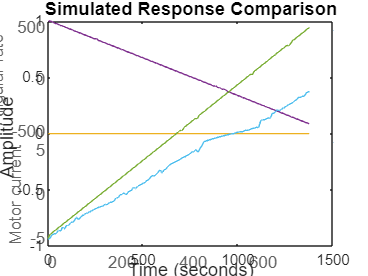

%%
%
% 2. Compare the simulated output with the measured data.
%
% |compare| displays both measured and simulated outputs of one or more
% models, whereas |predict|, called with the same input arguments, displays
% the simulated outputs.
%
% The simulated and measured outputs are shown in a plot window.
compare(z, nlgr);

%% Parameter Estimation
% Estimate the parameters and initial states using |nlgreyest|, which is a
% prediction error minimization method for nonlinear grey box models. The
% estimation options, such as the choice of estimation progress display,
% are specified using the "nlgreyestOptions" option set.
nlgr = setinit(nlgr, 'Fixed', {false false}); % Estimate the initial states.
opt = nlgreyestOptions('Display', 'on');
nlgr = nlgreyest(z, nlgr, opt);

%% Performance Evaluation of the Estimated DC-Motor Model
% 1. Review the information about the estimation process.
%
% This information is stored in the |Report| property of the
% |idnlgrey| object. The property also contains information about how the
% model was estimated, such as solver and search method, data set, and why
% the estimation was terminated.
nlgr.Report
fprintf('\n\nThe search termination condition:\n')
nlgr.Report.Termination

%%
% 2. Evaluate the model quality by comparing simulated and measured
% outputs.
% 
% The fits are 98% and 84%, which indicate that the estimated model
% captures the dynamics of the DC motor well.
compare(z, nlgr);

%%
% *Figure 4:* Comparison between measured outputs and the simulated outputs
% of the estimated IDNLGREY DC-motor model.

%%
%
% 3. Compare the performance of the |idnlgrey| model with a second-order
% ARX model.
na = [2 2; 2 2];
nb = [2; 2];
nk = [1; 1];
dcarx = arx(z, [na nb nk]);
compare(z, nlgr, dcarx);

%%
% 4. Check the prediction errors.
%
% The prediction errors obtained are small and are centered around zero
% (non-biased).
pe(z, nlgr);